# Exercise: CORA

We will start with a short introduction to CORA and then take a look at some common set representation we will use.

## CORA - A Tool for COntinuous Reachability Analysis

### Download & Installation

Website: [https://tumcps.github.io/CORA/](https://tumcps.github.io/CORA/) [1]

DON'T download CORA via the Add-On Manager. Instead, ask Tobias for access to the cora repository: [https://bitbucket.org/MatthiasAlthoff/cora/src/master/](https://bitbucket.org/MatthiasAlthoff/cora/src/master/)

After downloading, add the path of CORA (inluding subfolders) to your path (H`ome > ENVIRONMENT > Set Path`).

After that, you can install the requirements for CORA listed in the manual: [https://tumcps.github.io/CORA/data/Cora2022Manual.pdf](https://tumcps.github.io/CORA/data/Cora2022Manual.pdf) (in general very usefull! Make sure to save it.)

For importing trained neural networks into CORA, we need two additional toolboxes. Again, these can be installed via the Add-Ons window as well.

- [Deep Learning Toolbox](https://de.mathworks.com/help/deeplearning/index.html?s_tid=CRUX_lftnav) 

- [Deep Learning Toolbox Converter for ONNX Model Format](https://de.mathworks.com/matlabcentral/fileexchange/67296-deep-learning-toolbox-converter-for-onnx-model-format)

### Git Branch

Make sure you are on the main nn development branch of CORA.

`    git pull origin nn-main`

`    git checkout nn-main`

Please add all new folders to your path: `Home > ENVIRONMENT > Set Path`, then `Add with Subfolders` and choose the cora root directory.

**Important: **Please create your own branch to develop and test. Add the `nn-` prefix to indicate a neural network development branch.

`    git branch nn-<your-branch-name>`

`    git checkout nn-<your-branch-name>`

If you have everything installed correctly, the following should return 1.

testnn_requiredToolboxes

ans = logical
   1


### Introduction & Outlook

CORA is a toolbox for COntinuous Reachability Analysis. If you are unfamiliar with the term, the following high-level understanding is enough for now.

Imagine two cars driving on a single-lane street. Each car has a current location $l$, velocity $v$ and acceleration $a$.

From that, we can derive the dynamic of a our system via ordinary differential equations (ODE):

- ${\dot{l} }_i =v_i$ (the change of the location depends on the velocity)

- ${\dot{v} }_i =a_i$ (the change of the velocity depends on the acceleration)

- ${\dot{a} }_i =u_i$ (the change of the acceleration depends on the driver's input $u_i$)

- 
$$i\in \left\lbrace 1,2\right\rbrace$$


dynamics = @(x, u) [ % x is current state, u is the input
    % car 1
    x(2); % \dot{l}_1 = v_1
    x(3); % \dot{v}_1 = a_1
    u(1); % \dot{a}_1 = u_1 | input of driver 1
    % car 2
    x(5); % \dot{l}_2 = v_2
    x(6); % \dot{v}_2 = a_2
    u(2); % \dot{a}_2 = u_2 | input of driver 2
];

We will use these dynamics as a toy example to demonstrate CORA's functionalities.

We can now simulate this dynamic system using CORA by defining an initial condition.

For now, we consider car 1 in front of car 2 as defined below. Car 1 drives a bit faster than car 2, however, the driver of car 2 starts to accelerate while the driver in car 1 keeps its speed.

sys = nonlinearSys(dynamics);
x_0 = [ % initial condition
    % car 1
    100;    % l1 [m] (location)       
    50;     % v1 [m/s] (velocity)
    0;      % a1 [m/s^2] (acceleration)
    % car 2
    0;      % l2 [m] (location)
    30;     % v2 [m/s] (velocity)
    0       % a2 [m/s^2] (acceleration)
];

u = [ % driver's input
    0; % \dot{a}_1 (car 1 keeps speed)
    5; % \dot{a}_2 (car 2 accelerates)
];

Let us simulate this scenario over the next 5 seconds!

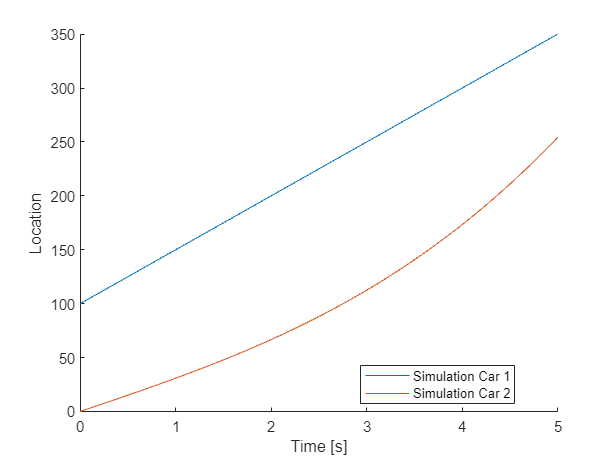

params = struct;
params.tFinal = 5;
params.R0 = zonotope(x_0);
params.U = zonotope(u);

sim = simulateRandom(sys, params);

figure; hold on;
% '1' is the dimension the location of car 1 in x/sim
run1 = plotOverTime(sim, 1, 'DisplayName',"Simulation Car 1");
% '4' is the dimension the location of car 2 in x/sim
run2 = plotOverTime(sim, 4, 'DisplayName',"Simulation Car 2"); 
xlabel("Time [s]")
ylabel("Location")
legend('Location', "best")

All good, right? Car 2 doesn't  crash into car 1!

**However, **are you sure the cars are exactly at the given location, driving at exactly the given speed? What about sensor inaccuracies?

We can model such **uncertainties **with CORA. Consider the following uncertainties at t=0;

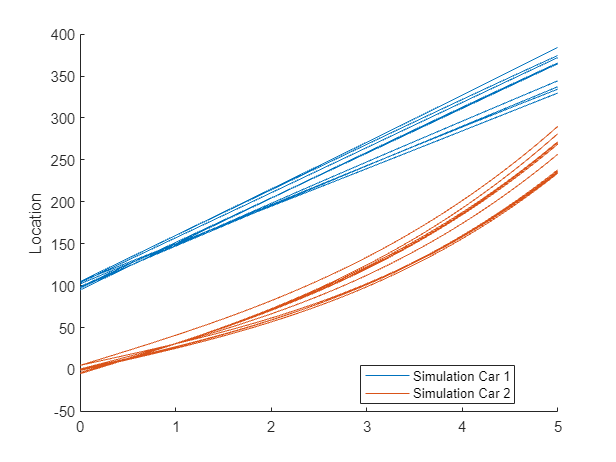

% add uncertainty
uncertainty = [ % at time t=0
    5;   % s +/- 5m
    5;   % v +/- 5m/s
    0.1; % a +/- 1m/s^2
];
params.R0 = zonotope(x_0, diag([uncertainty; uncertainty]));
params.U = zonotope(u, 0.5*eye(2));

sim = simulateRandom(sys, params);

figure; hold on;
run1 = plotOverTime(sim, 1, 'DisplayName',"Simulation Car 1");
run2 = plotOverTime(sim, 4, 'DisplayName',"Simulation Car 2");

ylabel("Location")
legend([run1, run2], "Simulation Car 1", "Simulation Car 2", Location="best")

Now the distance between the two cars is much smaller. How can you be sure, that car 2 doesn't crash into car 1 for the given specifications?

Maybe there is an outlier run of car 2 which accelerates just a bit faster and thus crashes into one of the slower runs of car 1?

We can verify that no such scenario exists using CORA. We will now compute the reachable set, i.e. all possible states we can reach over the next 5 seconds. Thus, all simulation runs are within the reachable set. 

As the reachable set cannot be computed exactly in general (see Cyber-Physical Systems & Formal Methods Lecture), we compute an over-approximation of the set.

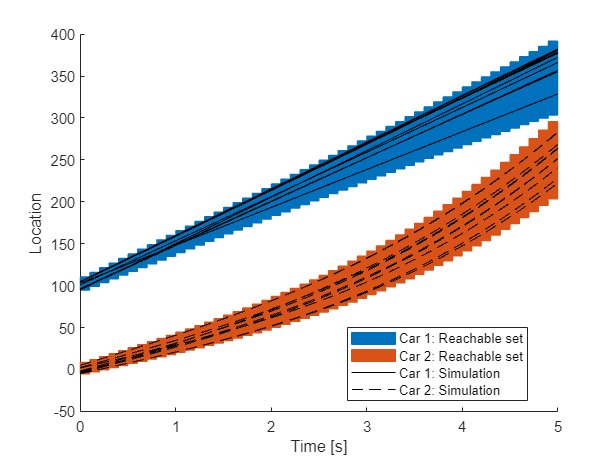

% further parameters to compute the reachable set (you can ignore them for now)
options = struct;
options.alg = 'lin';
options.tensorOrder = 2;
options.timeStep = 0.1;
options.taylorTerms = 4;
options.zonotopeOrder = 250;

% compute reachable set
sim = simulateRandom(sys, params);
R = reach(sys, params, options);
figure; hold on;
car1 = plotOverTime(R, 1, 'DisplayName', 'Car 1: Reachable set');
car2 = plotOverTime(R, 4, 'DisplayName', 'Car 2: Reachable set');
run1 = plotOverTime(sim, 1, 'k', 'DisplayName', 'Car 1: Simulation');
run2 = plotOverTime(sim, 4, '--k', 'DisplayName', 'Car 2: Simulation');
xlabel("Time [s]")
ylabel("Location")
legend('Location', "best")

As the reachable sets of both cars don't intersect, we have formally verified that the cars won't crash into each other over the next 5 seconds.

In this practical course, we consider the formal **verification of neural networks. **Neural networks are still a black-box in many cases, i.e. the explainability of their output is hard (even NP-hard!) and often surprising (see later exercises). With the success of neural networks, also the verification of neural networks is becoming an important topic over the last couple of years.

You can easily image car 2 to be controlled by a neural network. Can we verify that car 2 keeps a safe distance to the leading car given unkown outputs of the neural network? This is precicely what the following example verifies:

BENCHMARK: Adaptive Cruise Controller (ACC)
Time to compute random simulations: 0.88512
Time to check violation in simulations: 0.009499
Time to compute reachable set: 1.6019
Time to check verification: 0.043547
Total Time: 2.5401
Result: VERIFIED
Plotting..


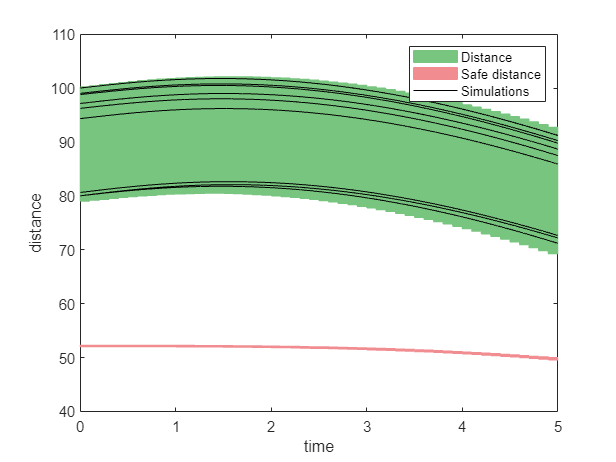

example_neuralNet_reach_02_ACC();

**Task 2.1**

- Get familiar with CORA by playing around with the initial condition and uncertainties of our toy example above.

- Are you able to find a run that cannot be verified?

- Are you able to find a run that can be verified?

- Can you imagine another scenario where this approach can be applied?

*(just type the answers into this MATLAB live script. It will be exported as pdf at the end of the script.)*

To calculate these reachable sets, we use set representations, which we will also use for the **verification of neural networks** later.

### Set Representations

Here we will show off some set representations as well as some simple operations. They represent the core to everything we do in CORA, so getting an intuition for those is very helpful for working using CORA.

Further information, examples and all operations can be found in the manual: [https://tumcps.github.io/CORA/data/Cora2021Manual.pdf](https://tumcps.github.io/CORA/data/Cora2021Manual.pdf) and on the website [cora.in.tum.de](http://cora.in.tum.de).

#### Interval

A very simple set representation is the interval, containing all values within the given bounds. Thus, all borders are axis alligned.


$$I=\left\lbrace x\in R^n \;|\;l\le x\le u\right\rbrace$$


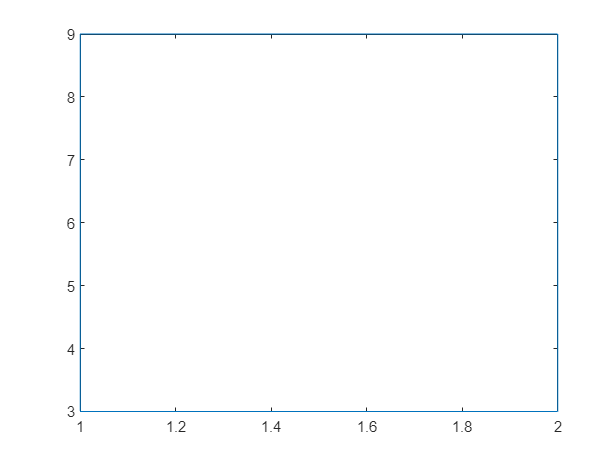

bounds = [
    1, 2;  % dim 1
    3, 9   % dim 2
];
% interval constructor expects lower and upper bounds as parameters
I = interval(bounds(:, 1), bounds(:, 2));

figure;
plot(I)

We can also sample some random points from this interval:

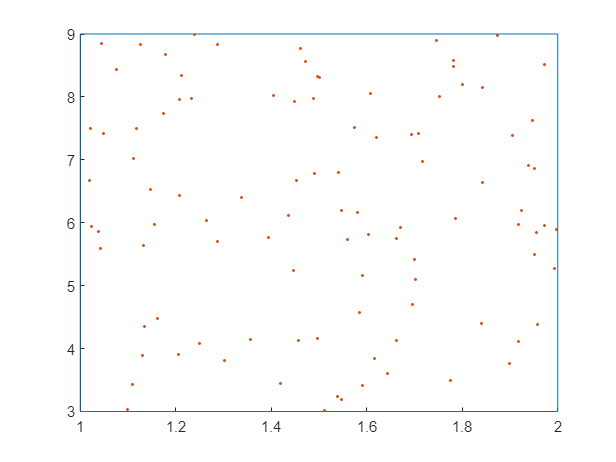

points = I.randPoint(100);

figure; hold on;
plot(I)
scatter(points(1, :), points(2, :), '.')

#### Zonotopes

A more complex set representation is given by zonotopes. These can capture a variety of convex set representations.


$$Z=\left\lbrace c+\sum_{i=1}^p \beta {\;}_i \cdot g^{\left(i\right)} \;|\;\beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


c represents the center of the zonotope. Each column in G represents a generator vector $g^{\left(i\right)} \;$. Each of these generators have a dependent factor $\beta {\;}_i$ attached such they span a line from $-g^{\left(i\right)} \;$ to $g^{\left(i\right)} \;$. Combined* with the other generators, we can represent convex sets.

*Combined: We use the Minkowski Sum (see set operations below) to combine the lines from each generator.

c = [1;1];
G = [
    1 1 1; 
    2 -1 0
];
Z = zonotope(c,G)

Z =

dimension: 2

c: 
     1
     1

G: (3 generators)
     1     1     1
     2    -1     0



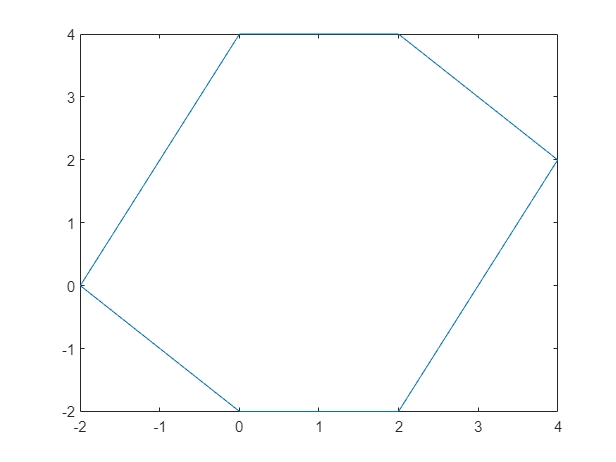

figure;
plot(Z)

Step-by-step construction:

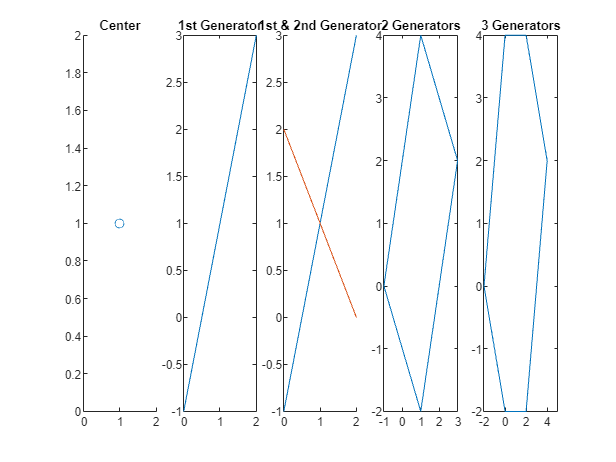

figure;
subplot(1,5,1); plot(zonotope(c)); title("Center")
subplot(1,5,2); plot(zonotope(c,G(:,1))); title("1st Generator")
subplot(1,5,3); hold on; plot(zonotope(c,G(:,1))); plot(zonotope(c,G(:,2))); title("1st & 2nd Generator")
subplot(1,5,4); plot(zonotope(c,G(:,1:2))); title("2 Generators")
subplot(1,5,5); plot(zonotope(c,G(:,1:3))); title("3 Generators")

**! ***Note: If the plot is too tiny, hover over the plot and click on the arrow on the top right. This should open the plot in a new window which you can resize to your needs. The code needs to be executed before.*

A more detailed plot with the generator vectors (only works for 3 generators):

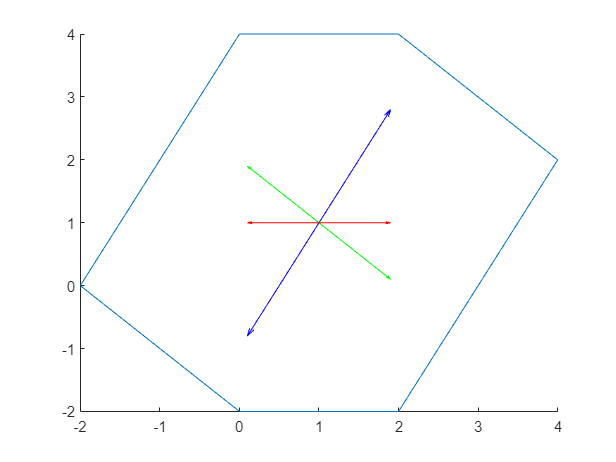

figure; hold on;
plot(Z)
drawArrow = @(x, y, c) quiver(x(1),x(2),y(1),y(2), c);
% first generator
drawArrow(c, G(:, 1), 'b');
drawArrow(c, -G(:, 1), 'b');

% second generator
drawArrow(c, G(:, 2), 'g');
drawArrow(c, -G(:, 2), 'g');

% third generator
drawArrow(c, G(:, 3), 'r');
drawArrow(c, -G(:, 3), 'r');

Note that e.g. the top right corner of the set can be reached as follows:

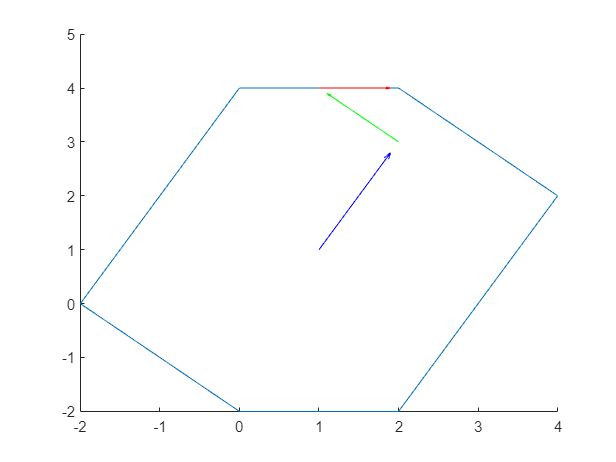

% combine generators
figure; hold on;
plot(Z)
drawArrow(c, G(:, 1), 'b');                 % beta1 = 1
drawArrow(c+G(:, 1), -G(:, 2), 'g');        % beta2 = -1
drawArrow(c+G(:, 1)-G(:, 2), G(:, 3), 'r'); % beta3 = 1

**Task: **Change the values of the generators and try to draw the set spanned by the zonotope below by hand to get a better feeling for them.

#### (Sparse) Polynomial Zonotopes

A more advanced version of the zonotopes are the polynomial zonotopes [2]. With these, we can also represent non-convex sets.

This can be achieved by having an additional dependent generator matrix as well as the independent generator matrix we had with zonotopes.


$$\textrm{pZ}=\left\lbrace c+\sum_{i=1}^h \left(\prod_{k=1}^p {\alpha \;}_k^{E_{k,i} } \right)\cdot {g_{\textrm{dep}} }^{\left(i\right)} +\sum_{i=1}^q \beta {\;}_i \cdot {g_{\textrm{ind}} }^{\left(i\right)} \;|\;\alpha_{i,\;} \beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


To make the dependent generators *dependent, *we introduce some shared ${\alpha \;}_k^{\;}$ and determine if (and how) they are used with the current generator i via the exponential map E, where a 0 means unused and any other value means used.

The following code block shows an example of a polynomial zonotope. How it is created is explained afterwards.

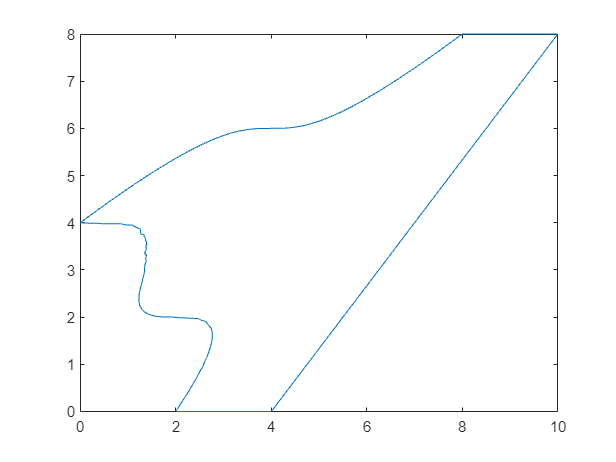

c = [4;4];
G = [ % dependent generator matrix
    2 1 2;
    0 2 2
];
E = [ % exponential map
    1 0 3;
    0 1 1
];
GI = [1;0]; % ingependent generator matrix
pZ = polyZonotope(c,G,GI,E);

figure;
plot(pZ)

This example defines the polynomial zonotope 


$$\textrm{pZ}=\left\lbrace \left\lbrack \begin{array}{c}
4\\
4
\end{array}\right\rbrack +\alpha_1 \left\lbrack \begin{array}{c}
2\\
0
\end{array}\right\rbrack +\alpha_2 \left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack +\alpha_1^3 \alpha_2 \left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack +{\beta \;}_1 \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack |\;\alpha_{i,\;} \beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


The construction of this polynomial zonotope is visualized in the figure below: 

    (a) shows the set spanned by the constant offset vector and the first and second dependent generator, 

    (b) shows the addition of the dependent generator with the mixed term $\alpha_1^3 \alpha_2$, 

    (c) shows the addition of the independent generator, and 

    (d) visualizes the final set.

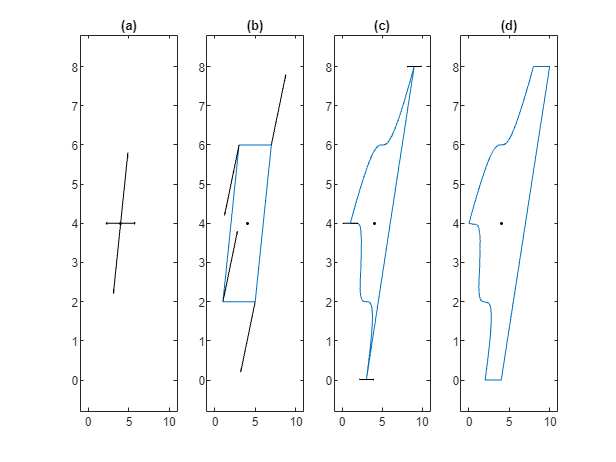

example_manual_polyZonotope_construction

**! ***Note: If the plot is too tiny, hover over the plot and click on the arrow on the top right. This should open the plot in a new window which you can resize to your needs. The code needs to be executed before.*

To get more information on the polynomial Zonotope, use:

pZ

pZ =

c: 
     4
     4

G: (3 generators)
     2     1     2
     0     2     2

GI: (1 generator)
     1
     0

E: (3 generators)
     1     0     3
     0     1     1

id: (2 ids)
    (1:2)'


### Set Operations

We only show the two most important set operations here. Further operations can be found in the Manual: [https://tumcps.github.io/CORA/data/Cora2022Manual.pdf](https://tumcps.github.io/CORA/data/Cora2021Manual.pdf)

#### Minkowski Sum

The Minkowski Sum adds two sets together:


$$S_1 \oplus S_2 =\left\lbrace s_1 +s_2 \;|\;s_1 \in S_1 ,s_2 \in S_2 \right\rbrace$$


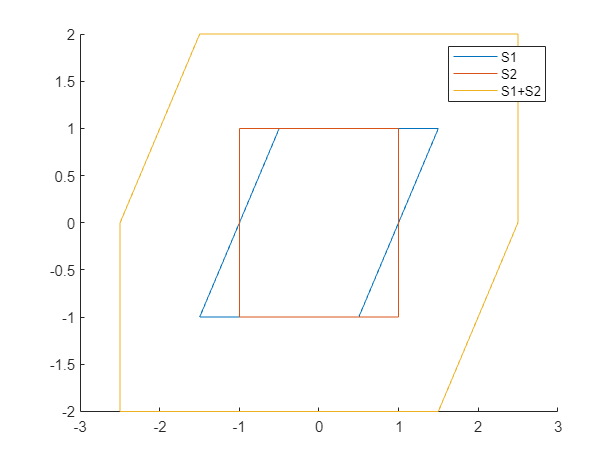

% set S1 and S2
S1 = zonotope([0;0], [0.5 1; 1 0]);
S2 = zonotope([0;0], [1 0; 0 1]);
% Minkowski sum
res = S1 + S2;

figure; hold on;
plot(S1, [1, 2], 'DisplayName', 'S1');
plot(S2, [1, 2], 'DisplayName', 'S2');
plot(res, [1, 2], 'DisplayName', 'S1+S2');
legend()

This operation is also used to add the lines spanned by the generators of zonotopes together.

#### Affine Map

The Affine Map performs a linear transformation on a set, e.g. scaling, rotating, etc.

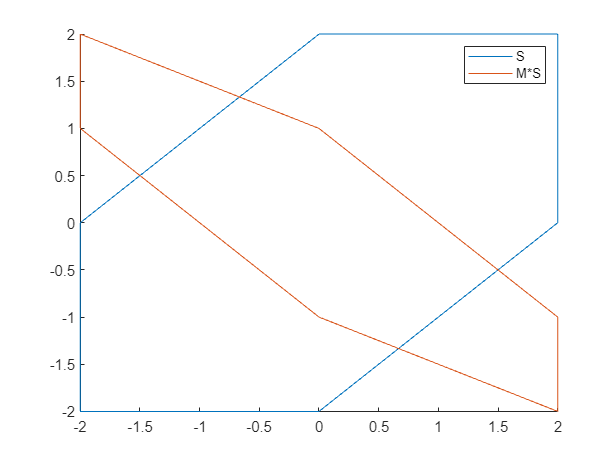

% set and matrix
S = zonotope([0 1 1 0; 0 1 0 1]);
M = [1 0; -1 0.5];
% linear transformation
MS = M * S;

figure; hold on;
plot(S, [1,2], "DisplayName", "S")
plot(MS, [1,2], "DisplayName", "M*S")
legend()

**Tasks 2.2**

- Get an intuition for set representations and their operations.

- Play around with different values.

- Have a look into the references below.

Any question? Just ask!

### Export to PDF

Export the live script as pdf and send the results back to Tobias ([tobias.ladner@tum.de](mailto:tobias.ladner@tum.de)). Make sure that all tasks are solved and all results are visible in the pdf. If they are not visible, make sure the file is saved (unsaved files have a * next to their name in the tab list above) and rerun this section.

filePath = matlab.desktop.editor.getActiveFilename;
pdfPath = convertStringsToChars(strrep(filePath, ".mlx", ".pdf"));
matlab.internal.liveeditor.openAndConvert (filePath, pdfPath);

## References

[1]  Althoff, M. (2015). An introduction to CORA 2015. In *Proc. of the workshop on applied verification for continuous and hybrid systems* (pp. 120-151).

- Cora Website: [https://tumcps.github.io/CORA/](https://tumcps.github.io/CORA/)

- Cora Manual: [https://tumcps.github.io/CORA/data/Cora2022Manual.pdf](https://tumcps.github.io/CORA/data/Cora2022Manual.pdf)

- Cora Git Repository: [https://bitbucket.org/MatthiasAlthoff/cora/src/master/](https://bitbucket.org/MatthiasAlthoff/cora/src/master/)

[2] Kochdumper, N., & Althoff, M. (2020). Sparse polynomial zonotopes: A novel set representation for reachability analysis. *IEEE Transactions on Automatic Control*, *66*(9), 4043-4058.

[3] Makino, K., & Berz, M. (2003). Taylor models and other validated functional inclusion methods. *International Journal of Pure and Applied Mathematics*, *6*, 239-316.